# PGD Approximation of a random space-time field 

# - A POSTERIORI-

*V. Matray*

*Aicha Maaoui*

clear all
close all
clc

**Time discretisation**

T   = 10; 
n_T = 400; 
tf  = linspace(0,T,n_T);     % fine discretisation
tc  = linspace(0,T,n_T/10);  % coarse discretisation
dt  = tf(2); % time step

**Space discretisation**

L = 1; 
n_X = 200; 
xf  = linspace(0,L,n_X);    % fine discretisation
xc  = linspace(0,L,n_X/10); % coarse discretisation
dx  = xf(2);

**Display of the field smoothed to approximated by PGD **

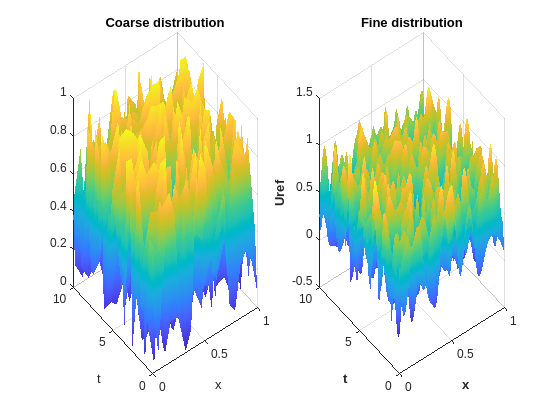

% Meshes (fine and coarse)
[mesh_x_f,mesh_t_f] = meshgrid(xf,tf);
[mesh_x_g,mesh_t_g] = meshgrid(xc,tc);

% Random function on the coarse mesh:
Ug = rand(n_T/10,n_X/10);

% Interpolation on the fine mesh to get a 
% smooth distribution : (If the field is too discontinuous
% the PGD will have trouble approximating it: 
% you can check this at the end of the session).
Uf = interp2(mesh_x_g,mesh_t_g,Ug,mesh_x_f,mesh_t_f,'spline');

% Display distribution
figure()
subplot(1,2,1)
surf(xc,tc,Ug)
xlabel('x')
ylabel('t')
title("Coarse distribution")
shading interp

subplot(1,2,2)
surf(xf,tf,Uf)
xlabel('x', 'FontWeight','bold')
ylabel('t', 'FontWeight','bold')
zlabel('Uref', 'FontWeight','bold')
title("Fine distribution")
shading interp

## Elementary matrix and assembly for integration 

% Space
Ix = 4 * diag(ones(1,n_X));
Ix(1,1) = 2; 
Ix(n_X,n_X) = 2; 
Ix = (dx/6)*(Ix+ diag(ones(1,n_X-1), -1) + diag(ones(1,n_X-1), 1));

% Time
It = 4 * diag(ones(1,n_X));
It(1,1) = 2; 
It(n_T,n_T) = 2; 
It = (dt/6)*(It+ diag(ones(1,n_T-1), -1)+ diag(ones(1,n_T-1), 1));

## PGD Approximation

% Initialization of the global variables
n_modes    = 20; % Number of modes
Threshold = 10e-3; %Fixed threshold

**Greedy algorithm + fixed point **

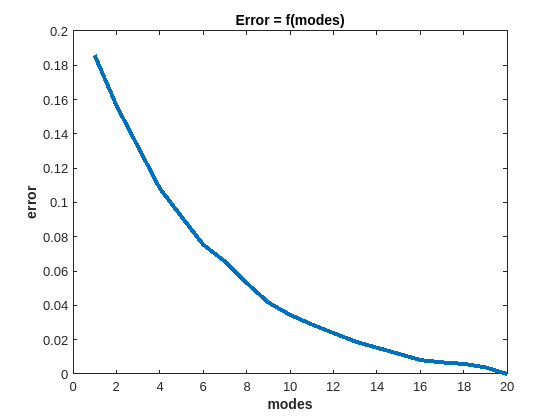

% Call the greedy + fixed point algorithm    
[PGD_error,U_PGD] = GreedyNoOrthogonalization(Uf,n_modes, n_X,n_T,T,It,Ix,Threshold);

% Plot the error with spatio-temporal norm
figure()
plot(1:n_modes,PGD_error, 'LineWidth', 3)
xlabel('modes', 'FontWeight','bold')
ylabel('error', 'FontWeight','bold')
title("Error = f(modes)")

**Reconstruct the field**

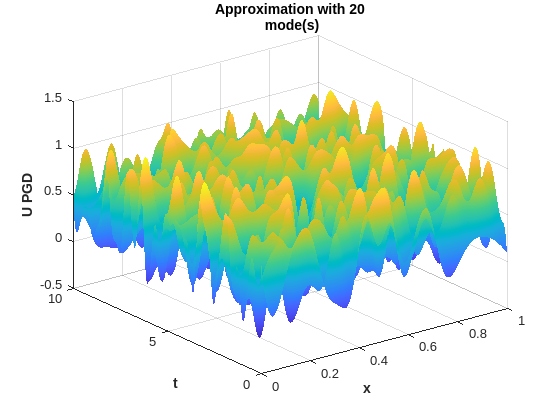

% Reconstruct the image with the number of modes
figure()
surf(mesh_x_f,mesh_t_f,U_PGD)
xlabel('x', 'FontWeight','bold')
ylabel('t', 'FontWeight','bold')
zlabel('U PGD', 'FontWeight','bold')
shading interp
Title = ["Approximation with "+ n_modes " mode(s)"];
title(Title)

**Orthogonalization using Gram-Schmidt algorithm**

% Get error and approximated field
[PGD_error_orth,U_PGD_orth] = GreedyOrthogonalization(Uf,n_modes, n_X,n_T,T,It,Ix,Threshold);

% Plot the error with spatio-temporal norm
plot(1:n_modes,PGD_error_orth, 'LineWidth', 3)
xlabel('modes', 'FontWeight','bold')
ylabel('error', 'FontWeight','bold')
title("Error = f(modes)")

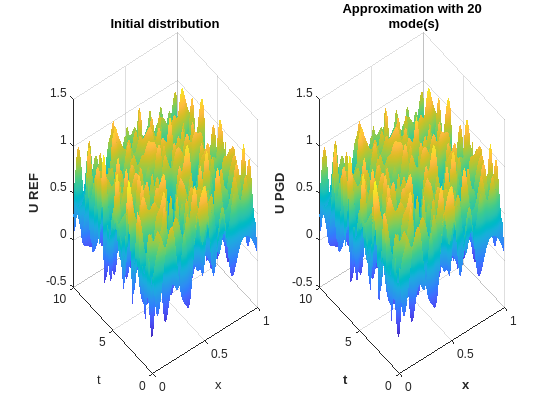

% Plotting of the reconstructed field
figure()
subplot(1,2,1)
surf(xf,tf,Uf)
xlabel('x')
ylabel('t')
zlabel('U REF', 'FontWeight','bold')
title("Initial distribution")
shading interp

subplot(1,2,2)
surf(mesh_x_f,mesh_t_f,U_PGD_orth)
xlabel('x', 'FontWeight','bold')
ylabel('t', 'FontWeight','bold')
zlabel('U PGD', 'FontWeight','bold')
Title = ["Approximation with "+ n_modes " mode(s)"];
title(Title)

shading interp

**Comparison of errors with and without orthogonalization**

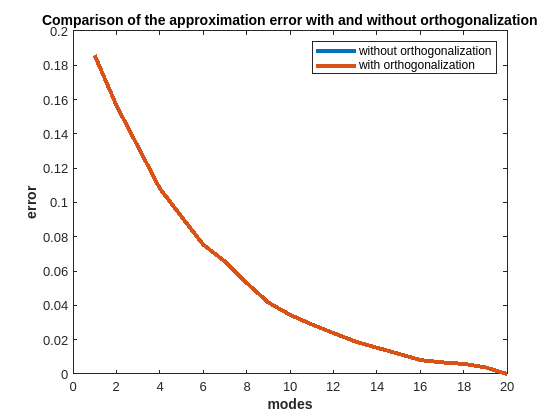

figure()
plot(1:n_modes,PGD_error,1:n_modes,PGD_error_orth, 'LineWidth', 3);
xlabel('modes', 'FontWeight','bold')
ylabel('error', 'FontWeight','bold')
legend("without orthogonalization", "with orthogonalization")
title('Comparison of the approximation error with and without orthogonalization')

## **Application to "Maria Callas" image**

**Orthogonalized PGD applied on the image**

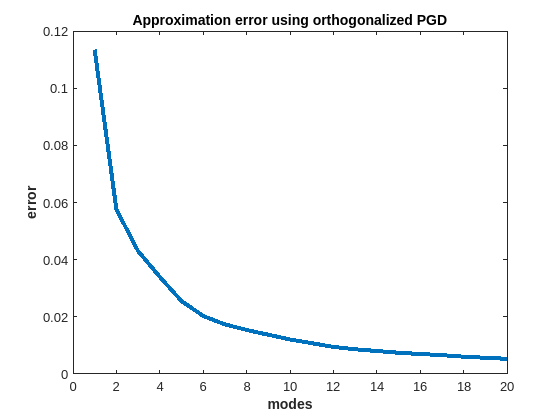


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%      Step 0 : Load the image and extract its properties (dimensions)      %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Load image
UCimage = imread('callas.jpg');
UCimage = im2double(UCimage(:,:,1));

% Get image dimensions
img_n_T = size(UCimage, 1);
n_M = size(UCimage, 2);
M = UCimage;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%                 Step 1 : Elementary matrices calculation                  %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Space
img_Ix = 4 * diag(ones(1,n_M));
img_Ix(1,1) = 2; 
img_Ix(n_M,n_M) = 2; 
img_Ix = (1/6)*(img_Ix+ diag(ones(1,n_M-1), -1) + diag(ones(1,n_M-1), 1));

% Time
img_It = 4 * diag(ones(1,img_n_T));
img_It(1,1) = 2; 
img_It(img_n_T,img_n_T) = 2; 
img_It = (1/6)*(img_It+ diag(ones(1,img_n_T-1), -1)+ diag(ones(1,img_n_T-1), 1));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%               Step 3 : Greedy algorithm with integration                  %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

img_T = 600;
[img_PGD_err,img_U_PGD] = GreedyOrthogonalization(M,n_modes, n_M, img_n_T,img_T, img_It,img_Ix,Threshold);

% Plotting of the error with saptio-temporal norm
figure(2)
plot(1:n_modes,img_PGD_err, 'LineWidth', 3)
xlabel('modes', 'FontWeight','bold')
ylabel('error', 'FontWeight','bold')
title('Approximation error using orthogonalized PGD', 'FontWeight','bold')

**Compare the SVD and PGD with orthogonalization**

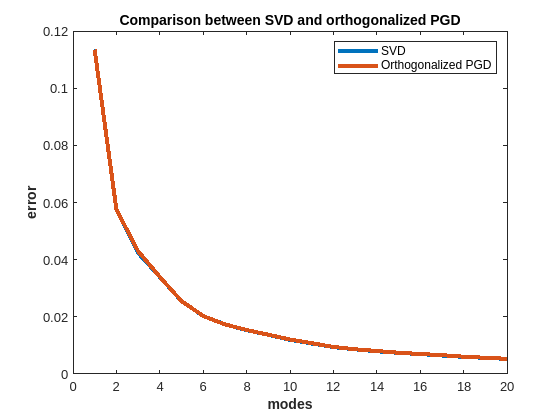

[U,S,V] = svd(M);
M_POD = zeros(n_M,n_T)';
err_svd = zeros(n_modes,1);
int1_t = zeros(n_M,1);
int2_t = zeros(n_M,1);
for n= 1:n_modes
        M_POD = U(:,1:n)*S(1:n,1:n)*V(:,1:n)';
        % Calculate the approximation error
        for j = 1:n_M
            int1_t(j) = (M(:, j) - M_POD(:, j))' * img_It * (M(:, j) - M_POD(:, j));
            int2_t(j) = (M(:, j))'*img_It*(M(:, j));
        end
        int1_x = (int1_t)'*img_Ix*(int1_t);    
        int2_x = (int2_t)'*img_Ix*(int2_t);
        e_svd = (int1_x)/(int2_x);
        err_svd(n) = sqrt(e_svd);
end

plot(1:n_modes,err_svd,1:n_modes,img_PGD_err, 'LineWidth', 3)
xlabel('modes', 'FontWeight','bold')
ylabel('error', 'FontWeight','bold')
legend('SVD','Orthogonalized PGD')
title('Comparison between SVD and orthogonalized PGD', 'FontWeight','bold')

**Reconstruction of the image using PGD and SVD**

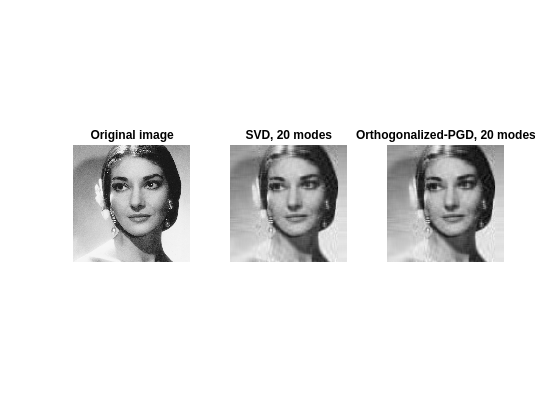

figure()

% Initial image
subplot(1,3,1)
colormap(gray); imagesc(M(:,:));axis equal;axis tight; axis off;
title("Original image", 'FontWeight','bold')

% Reconstruction using SVD
subplot(1,3,2)
colormap(gray); imagesc(M_POD(:,:));axis equal;axis tight; axis off;
title("SVD, "+n_modes+" modes", 'FontWeight','bold')

% Reconstruction using orthogonalized-PGD
subplot(1,3,3)
colormap(gray); imagesc(img_U_PGD(:,:));axis equal;axis tight; axis off;
title("Orthogonalized-PGD, "+n_modes+" modes", 'FontWeight','bold')

#### **Function : Greedy + Fixed point algorithm without orthogonalization (for multiple use)**

function [PGD_error,U_PGD] = GreedyNoOrthogonalization(Uf,n_modes, n_X,n_T,T,It,Ix,Threshold)

    % Initialization
    Lambda     = zeros(n_X,n_modes); % selon x
    Gamma      = zeros(n_T,n_modes); % selcon t
    U_PGD      = zeros(n_T,n_X);
    PGD_error = zeros(n_modes,1);    
    integration1_t = zeros(n_X,1);
    integration2_t = zeros(n_X,1);

    % Loop on the number of modes
    for mode = 1:n_modes

        % Add new mode (= eigenvector)
        U_star = Uf - U_PGD; % Field to approximate
        %U_PGD = Lambda*Gamma'; 
        
        gamma_new = linspace(0,T,n_T)';
    
        s=1;
        % Fixed point algorithm
        while (s> Threshold)
    
            % Save old function Gamma
            gamma_old = gamma_new;
            
            % Compute new space function Lambda
            Lambda_new = (U_star'*It*gamma_new)/(gamma_new'*It*gamma_new);
            
            % Normalization
            Lambda_new = Lambda_new / norm(Lambda_new);
            
            % Compute new time function 
            gamma_new = (U_star*Ix*Lambda_new)/(Lambda_new'*Ix*Lambda_new);
            
            % update stagnation criteria
            s = ((gamma_new-gamma_old)' * It * (gamma_new-gamma_old)) / (gamma_old'* It * gamma_old);
            
        end
    
        % Save the modes
        Lambda(:,mode)=Lambda_new;
        Gamma(:,mode)=gamma_new;
        U_PGD = U_PGD + gamma_new * Lambda_new';
    
        % Update the field to approximate
        U_star = U_star - gamma_new * Lambda_new';
    
        % Calculate the approximation error
        for j = 1:n_X
            integration1_t(j) = (Uf(:, j) - U_PGD(:, j))' * It * (Uf(:, j) - U_PGD(:, j));
            integration2_t(j) = (Uf(:, j))'*It*(Uf(:, j));
        end
        integration1_x = (integration1_t)'*Ix*(integration1_t);    
        integration2_x = (integration2_t)'*Ix*(integration2_t);
        e = (integration1_x)/(integration2_x);
        PGD_error(mode) = sqrt(e);
    
    end   
end

#### **Function : Orthogonalization using Gram-Schmidt algorithm (for multiple use)**

function [PGD_error_orth,U_PGD] = GreedyOrthogonalization(Uf,n_modes, n_X,n_T,T,It,Ix,Threshold)

    % Initialization
    Lambda     = zeros(n_X,n_modes); % selon x
    Gamma      = zeros(n_T,n_modes); % selon t
    U_PGD      = zeros(n_T,n_X);    
    PGD_error_orth = zeros(n_modes,1);
    integration1_t_orth = zeros(n_X,1);
    integration2_t_orth = zeros(n_X,1);

    % Loop on the number of modes
    for mode = 1:n_modes
    
        % Add new mode 
        U_star = Uf - U_PGD; % Field to approximate

        gamma_new = linspace(0,T,n_T)'; % initialization of gamma_new (choice)
    
        s=1;
        % Fixed point algorithm
        while (s> Threshold)
    
            % Save old function Gamma
            gamma_old = gamma_new;
            
            % Compute new space function Lambda
            Lambda_new = (U_star'*It*gamma_new)/(gamma_new'*It*gamma_new);
            
            % Normalisation
            Lambda_new = Lambda_new / norm(Lambda_new);
            
            % Compute new time function 
            gamma_new = (U_star*Ix*Lambda_new)/(Lambda_new'*Ix*Lambda_new);
            
            % update stagnation criteria
            s = ((gamma_new-gamma_old)' * It * (gamma_new-gamma_old)) / (gamma_old'* It * gamma_old);
            
        end
    
        % Save the modes
        Lambda(:,mode)=Lambda_new;
        Gamma(:,mode)=gamma_new;
        U_PGD = U_PGD + gamma_new * Lambda_new';
    
        % Update the field to approximate
        U_star = U_star - gamma_new * Lambda_new'; 
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Orthogonalisation
         %We'll do this after we've successfully run the greedy
         % algorithm and managed to calculate the error in 
         % space-time. All we need to do here is to implement 
         % the Gram-Schmidt algorithm.
         % Note that mode orthogonalization is not useful here,
         % but it will be in the next TP 
         % (a priori use of the PGD).

        sum_orth = 0;
        for i = 1:(mode-1)
            sum_orth = sum_orth + (Lambda_new' * Ix * Lambda(:, i)) * Lambda(:, i);
            Gamma(:, i) = Gamma(:, i) + gamma_new * (Lambda_new' * Ix * Lambda(:, i));
        end
    
        Lambda_tmp = Lambda_new - sum_orth; % orthogonalized version of "Lambda_new"
        
        % Normalize the new mode
        Lambda_tmp = Lambda_tmp /sqrt(Lambda_tmp' * Ix * Lambda_tmp);
        gamma_new = gamma_new * sqrt(Lambda_tmp' * Ix * Lambda_tmp);
    
        % Save the normalized mode
        Lambda(:,mode) = Lambda_tmp;
    
        % Calculate the approximation error
        for j = 1:n_X
            integration1_t_orth(j) = (Uf(:, j) - U_PGD(:, j))' * It * (Uf(:, j) - U_PGD(:, j));
            integration2_t_orth(j) = (Uf(:, j))'*It*(Uf(:, j));
        end
        integration1_x_orth = (integration1_t_orth)'*Ix*(integration1_t_orth);    
        integration2_x_orth = (integration2_t_orth)'*Ix*(integration2_t_orth);
        e_orth = (integration1_x_orth)/(integration2_x_orth);
        PGD_error_orth(mode) = sqrt(e_orth);
       
    end
end